# Part II - Pre-tokenization: Forced Splits Using Regexp Patterns in GPT Series

In this section, we will explore how to use regular expression (regexp) patterns to enforce specific splits in the text processing pipeline within the GPT series. This technique can be particularly useful for handling complex tokenization requirements or ensuring that certain patterns are treated as distinct tokens.

Let's look at the GPT-2 paper "[Language Models are Unsupervised Multitask Learners](https://cdn.openai.com/better-language-models/language_models_are_unsupervised_multitask_learners.pdf)", where tokenization has been explained in the section "Input Representation". Accordingly, they didn't just applied the naive tokenizer algorithm we've just covered in the [Part I - Creating a Byte-Pair Encoding (BPE) Tokenizer from Scratch in MATLAB](https://anilyesilkaya.github.io/bpe-tokenizer-in-matlab/bpeTokenizer.html) but they've implemented a more specific regexp to the input text.

**Motivation:**

- We have common words like "dog" in the text, which will occur very frequently in certains formats such as `dog.`, `dog!`, `dog?` etc.

- We might think that the byte-pair encoding (BPE) algorithm is representing the word `dog` as a single token (`x`) and represents the punctuation with another token to represent; `dog. = [x, y], dog! = [x, z], dog? = [x, t]` etc. Hoever, this is not the case and this results in a sub-optimal allocation of limited vocabulary slots and model capacity.

**Solution:**

- We want to top-down manual enforce merging on the BPE algorithm.

Let's find the `encoder.py` file in the [GPT-2 GitHub repository](https://github.com/openai/gpt-2/tree/master) to check what GPT-2 does. If we check the lines 52-53, we will notice the following regexp pattern:

## Detailed Explanation of the GPT-2 Regexp Pattern

In this  section we will investigate of what exactly GPT-2 regexp pattern is doing.

- The wrapper `r"""_some_text_"""` represents that this is raw-string.

Therefore, the actual pattern itself becomes,

which can be represented in MATLAB as follows:

regexpPat = "'s|'t|'re|'ve|'m|'ll|'d| ?\p{L}+| ?\p{N}+| ?[^\s\p{L}\p{N}]+|\s+(?!\S)|\s+";
disp(regexpPat)

's|'t|'re|'ve|'m|'ll|'d| ?\p{L}+| ?\p{N}+| ?[^\s\p{L}\p{N}]+|\s+(?!\S)|\s+


- The first thing to note that this regexp is made up of a lot of OR conditions (`|`). For each text input, we would scan the regexp pattern from left-to-right until there is a match. 

Let's focus on the first part,

### Header part of the regexp

What does `'s|'t|'re|'ve|'m|'ll|'d` mean? From left-to-right find the string that matches the given pattern.

txt2 = "He's hello can't world they're how We've are i'm you they'll today continue'd";
regexpPat2 = "('s|'t|'re|'ve|'m|'ll|'d)";
txtMatch2 = regexp(txt2, regexpPat2, "match");
disp(txtMatch2)

    "'s"    "'t"    "'re"    "'ve"    "'m"    "'ll"    "'d"



Note that the problem with the above approach is that it won't be able to determine and match the UNICODE apostrophy,

txt3 = "He's hello can`t world they`re";
txtMatch3 = regexp(txt3, regexpPat2, "match");
disp(txtMatch3)

's


Another important point from the GPT-2 tokenizer file line 52 is the following comment:

Because of the lack of the ignorecase regexp won't be able to determine and match the uppercase apostrophy. Therefore, the tokenization will work different for uppercase and lowercase apostrophys,

txt4 = "He's hello can`t world THEY`RE";
txtMatch4 = regexp(txt4, regexpPat2, "match");
disp(txtMatch4)

's


### Middle part of the regexp

What does `[ ?\p{L}+]` mean? Optional space (`[ ?]`) - any kind of letter from any language (`[\p{L}]`) - one or more times (`[+]`). 

txt5 = "Hello world";
regexpPat5 = "('s|'t|'re|'ve|'m|'ll|'d| ?[a-zA-Z]+)";
txtMatch5 = regexp(txt5, regexpPat5, "match");
disp(txtMatch5)

    "Hello"    " world"



We can see from the above expression that the regexp skipped `['s]`, `['t]`, `['re]`, `['ve]`, `['m]`, `['ll]`, `['d],` and hit the expression `[ ?\p{L}+]`. Therefore, it matches with `"Hello"` and match ends here since the **whitespace is not a letter**. Then, a new match start and with `" world"` separately.

Here, instead of taking our string and feeding it into our tokenization procedure we are splitting it up first. All the separated text has been processed separately by the tokenizer and all the results of that processing are concatenated as a result of tokenization operation.

txt6 = "Hello world how are you";
txtMatch6 = regexp(txt6, regexpPat5, "match");
disp(txtMatch6)

    "Hello"    " world"    " how"    " are"    " you"



In other words, all of the elements of the string vector goes from text to token sequence independently an then the token sequence is going to be concatenated. It also effectively means that you only finding the merges among the elements of the string vector, which means that the `"e "` emerges from the `txtMatch2(4)` and `txtMatch2(5)` won't be appearing in the token sequence.

- What does `[ ?\p{N}+]` mean? Optional space (`[ ?]`) - any kind of numeric character in any script (`[\p{L}]`) - one or more times (`[+]`). Combining with the above regexp, the letters and the numbers are going to be separated.

txt7 = "Hello've world123 how are you";
regexpPat7 = "('s|'t|'re|'ve|'m|'ll|'d| ?[a-zA-Z]+| ?\d+)";
txtMatch7 = regexp(txt7, regexpPat7, "match");
disp(txtMatch7)

    "Hello"    "'ve"    " world"    "123"    " how"    " are"    " you"



- What does `[ ?[^\s\p{L}\p{N}]+]` mean? Optional space (`[ ?]`) - followed by something that is **not** a space, letter or number (`[^\s\p{L}\p{N}]`)  - one or more times (`[+]`). Which effectively tries to match the punctuation, not letters, not numbers, not whitespaces.

txt8 = "Hello've world123 how are you!!!?";
regexpPat8 = "('s|'t|'re|'ve|'m|'ll|'d| ?[a-zA-Z]+| ?\d+| ?[^\sa-zA-Z\d]+)";
txtMatch8 = regexp(txt8, regexpPat8, "match");
disp(txtMatch8)

    "Hello"    "'ve"    " world"    "123"    " how"    " are"    " you"    "!!!?"



### Tail part of the regexp

What does `[\s+(?!\S)]` mean? 

- Whitepace (`[\s+]`) - one or more times (`[+]`)

- Negative look-ahead asssertion (matching a whitespace up to without including the last whitespace character) (`[(?!\S)]`). 

Note that this is important since the whitespace characters are always in included at the beginning of the character/word so far and suppose we have a lot of spaces in our text,

where all the spaces up to `" world"` will be caught by this regexp.

txt9 = "Hello           world"

txt9 = "Hello           world"

regexpPat9 = "('s|'t|'re|'ve|'m|'ll|'d| ?[a-zA-Z]+| ?\d+| ?[^\sa-zA-Z\d]+|\s+(?!\S))";
txtMatch9 = regexp(txt9, regexpPat9, "match");
disp(txtMatch9)

    "Hello"    "          "    " world"



In essence, we can say that the GPT-2 tokenizer likes the format `[ word]`.

- Finally, the `[\s+]` part is for the last fallback to catch the trailing whitespaces.

txt10 = "Hello've world123 how's are           you!!!?    ";
regexpPat10 = "('s|'t|'re|'ve|'m|'ll|'d| ?[a-zA-Z]+| ?\d+| ?[^\sa-zA-Z\d]+|\s+(?!\S))|\s+";
txtMatch10 = regexp(txt10, regexpPat10, "match");
disp(txtMatch10)

    "Hello"    "'ve"    " world"    "123"    " how"    "'s"    " are"    "          "    " you"    "!!!?"    "    "



### A real world example

If we are trying to split the text which contains a piece of MATLAB code, let's see how the regexp handles it.

formatSpec = '%c';
fileID = fopen('example.txt','r'); % open the text file (read-only)
rawText = fscanf(fileID, formatSpec);
disp(rawText)

for i = 1:100
    if mod(i,3) == 0 && mod(i,5) == 0
    elseif mod(i,3) == 0
        disp("Fizz")
    elseif mod(i,5) == 0
        disp("Buzz")
    else
        disp(i)
    end
end



rawTxtMatch = regexp(rawText, regexpPat10, "match");
disp(rawTxtMatch.')

    {'for'     }
    {' i'      }
    {' ='      }
    {' 1'      }
    {':'       }
    {'100'     }
    {'↵   '    }
    {' if'     }
    {' mod'    }
    {'('       }
    {'i'       }
    {','       }
    {'3'       }
    {')'       }
    {' =='     }
    {' 0'      }
    {' &&'     }
    {' mod'    }
    {'('       }
    {'i'       }
    {','       }
    {'5'       }
    {')'       }
    {' =='     }
    {' 0'      }
    {'↵   '    }
    {' elseif' }
    {' mod'    }
    {'('       }
    {'i'       }
    {','       }
    {'3'       }
    {')'       }
    {' =='     }
    {' 0'      }
    {'↵       '}
    {' disp'   }
    {'("'      }
    {'Fizz'    }
    {'")'      }
    {'↵   '    }
    {' elseif' }
    {' mod'    }
    {'('       }
    {'i'       }
    {','       }
    {'5'       }
    {')'       }
    {' =='     }
    {' 0'      }
    {'↵       '}
    {' disp'   }
    {'("'      }
    {'Buzz'    }
    {'")'      }
    {'↵   '    }
    {' else'   }
    {'↵       '}
    {' disp'  

As we can see that the above list contains many elements, where the regexp splitted each element every time the category changes e.g. word, number, special character etc. Therefore, there won't be any token merges between those elements.

## Investigating GPT-2 and GPT-4 Tokenizers

We might think that in order to train the GPT-2 tokenizer OpenAI has used the regexp pattern we have above to split up text into chunks and then run the BPE over each chunk. However, it is exactly what they've done. Let's look at why, if we look at our example text,

The spaces in the lines `[        disp("Fizz")]` and `[        disp("Buzz")]` are never end up being merged in OpenAI's implementation, which we can check from the following web application: [GPT-2 Tokenizer Web App](https://tiktokenizer.vercel.app/?model=gpt2).

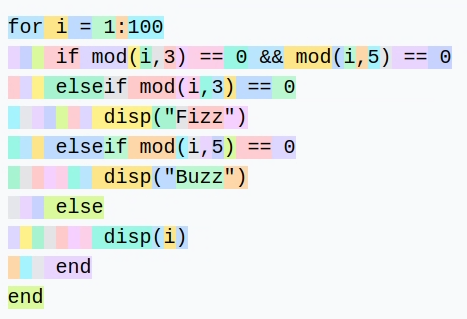

We can see from the above figure that each whitespace element (`[ ]`) in GPT-2 tokenizer is represented via the token `220`, where none of those are merged together to create a more compact representation. This implicity means that there are some additional rules on tokenization rather than chucking the raw text data on the BPE and obtain the tokens.

Note that the training code for the GPT-2 tokenizer is never been released and all we have as a datapoint is the lines 52 and 53 in the `encoder.py` file in the GPT-2 repository. Consequently, we don't exactly know how OpenAI trained their tokenizer.

% Configure the Python environment
pe = pyenv(Version="/home/ayesilka/.venvs/my_env_tiktoken/bin/python", ExecutionMode="OutOfProcess");

import py.tiktoken

% GPT-2 (does not merge spaces)
enc = py.tiktoken.get_encoding("gpt2");
disp(['GPT-2 encoder: ', enc.encode("      hello world!!!")])

Error using py.list/horzcat
Array formation and parentheses-style indexing with objects of class 'py.list' is not allowed. Use objects of class 'py.list' only as scalars or use a cell array.

### Special Tokens

In addition to the tokens that are coming as raw bytes (in UTF-8) in BPE merges we can also insert special tokens in our look-up table to delimit the text in various ways using special strings. If we look at the OpenAI's GPT-2 tokenizer it has the vocabuary size of `50 257`, where does that number come from?

- We know that there are `256` raw byte tokens

- OpenAI did `50 000` merges

- There is a special token, which is called `<|endoftext|>`, which is the very last token in the vocabulary is used to indicate the text data is coming from different sources. In other words, the special token shows the end of document, so that the we can signal the LLM that the document has ended and what came before is not informative for what comes next (at least this is our hope that this is what our LLM learns).

We can see from the picture above that the whole expression `<|endoftext|>` is encoded as a single token. How this works is that the special character is not going through the BPE merges instead bypasses it to handle the special tokens. The instructions to handle the special tokens are under the `lib.rs` file in the GPT-2 tokenizer repository. We can say that the special tokens are out of the BPE tokenization process.